# Data Cleaning Test File

**Author: Nina Matthews**

**Project: Masters Dissertation - Hierarchical portfolio stress-testing with flexible probabilities**

**Last edit: 18/07/2023**

**Supervisor: A/Prof. Tim Gebbie**

**Resources Used: **The MathWorks, Inc. (2019) 

## **Purpose**

*****

*****

*****

## **1. Environment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

**Set Directories **

Set path to function folder

% Add /functions directory 
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/dataprocessing/functions/'));

Set Image export path:

% use your default user path to create the filename and path
exportName = '';
imageExportpath = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Data Exploration/',exportName);

Set Processed data export path

dataExportpath = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/', exportName);

## 2. Data Pre-Processing

### 2.1 SIGNAL DATA: Load data (works but SAGDP is char)

fileName = "DATA-BB-SIG-M-20000223-20230323.xlsx";
fileName = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BLOOMBERG/SIGNAL',fileName);

Import per sheet and only keep certain field. importfields2keep only needed when excel has multiple sheets to import from. 

tickers2keep = {'PX_LAST'};
SIGSheetNames = sheetnames(fileName);
SIG_data = importfields2keep(tickers2keep,fileName, "A6");

#### 2.1.1 Address data types and frequencies: Change data type and interpolate GPD values

- SA GDP data type has text due to the NAs imported. Needs to be changed to double.

- SA GDP data is Quarterly -> needs to be changed using cubic-spline interpolation to monthly points

**Cubic-spline interpolation if wanted: **

% access the first element of the cell array with the timetable objects per
% cell and selects the first column in the first table and turns it into a
% row and assigns it to the value field of object GDPq

% GDP_quarterly = table2array(SIG_data{2});
% GDP_quarterly = str2double(GDP_quarterly);
% % Extract every third value from 2nd index
% GDP_quarterly = GDP_quarterly(2:3:end);
% time=height(SIG_data{2}(:,1));
% % current indexs for q values
% x_quarterly=2:3:time;
% % desired indexs for interpolated values
% x_monthly= 1:time;
% % cubic spline
% GDP_monthly = spline(x_quarterly,GDP_quarterly,x_monthly)';

**Zero-order hold interpolation if wanted: **

% Replace NaN values with the nearest previous non-NaN values
GDP_quarterly_TT = SIG_data{2};
GDP_quarterly_arr = str2double(table2array(GDP_quarterly_TT));
GDP_monthly = fillmissing(GDP_quarterly_arr, 'previous');
plot(GDP_quarterly_TT.Dates, GDP_monthly);
xlabel('Time');
ylabel('Data');
legend('Monthly Zero-order hold GDP','Location', 'northwest');
title('Quarterly to Monthly Data Interpolation');
hold off
close all

% Create a new timetable using the Dates from the existing timetable and GDP_monthly as values
GDP_Monthly_TT = timetable(SIG_data{2}.Dates, GDP_monthly, 'VariableNames', {'GDP_monthly'});
GDP_Monthly_TT.Properties.DimensionNames{'Time'} = 'Dates';
SIG_data{14} = GDP_Monthly_TT;
SIGSheetNames = [SIGSheetNames; 'SAGDP_M_INTERPOLATED'];

#### 2.1.2 Clean and convert into a single timetable by synchronize dates

% Synchronize all timetable objects in the cell array
SIG_dataTable = synchronize(SIG_data{:});
% rename variables
SIG_dataTable.Properties.VariableNames = SIGSheetNames;
% Display the synchronized timetable
disp(SIG_dataTable);

%######## Dropping GDP quartely  ######
SIG_dataTable = removevars(SIG_dataTable, "SAGDPANN Index");

When looking at the timetable we notice that there are inconsistencies with when certain signal indices are reported.  

#### **TO DO LATER Add start and end date as user definited properties (Possible new function to add)**

**Want to use it to automate date range added to file names when saving**

% % Get the date dimension of the timetable
% dateDim = SIG_dataTable.Properties.RowTimes;
% 
% % Get the first and last date elements
% startDate = min(dateDim);
% endDate = max(dateDim);
% 
% % Assign the start and end dates to new properties
% SIG_dataTable.Properties.UserData.startDate = startDate;
% SIG_dataTable.Properties.UserData.endDate = endDate;

#### 2.1.3 Missing data

 Plot before removing NA values: consistent with data not reported over weekends and holidays.

% missing data to plot in array
tickers = {'JALSHTR Index', 'OEZAKLAP Index', 'SACPIYOY Index', 'SAMYM3Y Index', 'JPEIGLBL Index', 'USDZAR Curncy', "NAPMPMI Index", "VIX Index", "SPX Index", "US0003M Index", "JIBA3M Index", "SAVIT40 Index", "SAGDP INTERP"};
na_array = transpose(isnan(table2array(SIG_dataTable)));
ax = axes;
spy(na_array, 'black-',5);
set(gca,'ytick',1:13,'yticklabel',tickers);
pbaspect([8 6 1]);
ylabel("State Variables");
xlabel("Date Index");
title("Missing Data PRE Date Alignment", 'FontSize', 13);
sig_NAplot = gcf;
hold off
% close all

**Export NA Data plot**

exportName = 'SIG_NAdata_plot.pdf';
exportgraphics(sig_NAplot,fullfile(imageExportpath,exportName),'Resolution',300);

#### 2.1.4 Exporting sample chunk of Misaligned data 

- to change to latex table for reporting

% Set time range to subset
TR_general = timerange('30-Sep-2009','31-Dec-2010');
sig_sample_tab = SIG_dataTable(TR_general,:);
%  = tail(SIG_dataTable)
% writetimetable(sig_sample_tab,'sig_sample_tab.xlsx');

#### 2.1.5 Fixing the inconsistent dates in the timetable objects

 Shift the timedate array of the individual state signal variables before synchronizing.

for signal = 1:width(SIG_data)
    SIG_data{1,signal}.Dates = dateshift(SIG_data{1,signal}.Dates, 'end', 'month');
end
SIG_aligned_data = SIG_data;

% Synchronize timetable objects 
SIG_aligned_dataTable = synchronize(SIG_aligned_data{:});
% rename variables
SIG_aligned_dataTable.Properties.VariableNames = SIGSheetNames;
% Display the synchronized timetable
disp(SIG_aligned_dataTable);

%######## Dropping GDP for now until ######
SIG_aligned_dataTable = removevars(SIG_aligned_dataTable, "SAGDPANN Index");

Plotting date adjusted data for signal data

% missing data to plot in array
tickers = {'JALSHTR Index', 'OEZAKLAP Index', 'SACPIYOY Index', 'SAMYM3Y Index', 'JPEIGLBL Index', 'USDZAR Curncy', "NAPMPMI Index", "VIX Index", "SPX Index", "US0003M Index", "JIBA3M Index", "SAVIT40 Index", "SAGDP INTERP"};
na_array = transpose(isnan(table2array(SIG_aligned_dataTable)));
ax = axes;
spy(na_array, 'black-',5);
set(gca,'ytick',1:13,'yticklabel',tickers);
pbaspect([8 6 1]);
ylabel("State Variables");
xlabel("Date Index");
title("Missing Data POST date alignment", 'FontSize', 13);
sig_alignedPlot = gca;

**Export NA Data plot**

exportName = 'SIG_alignedData_plot.pdf';
exportgraphics(sig_alignedPlot,fullfile(imageExportpath,exportName),'Resolution',300);
close all

**Extract the names of cols to change to valid field names (remove ' ',replace with '_')**

% rename the variables with underscores instead of spaces
newNames = strrep(SIG_aligned_dataTable.Properties.VariableNames, ' ', '_');
SIG_aligned_dataTable = renamevars(SIG_aligned_dataTable, SIG_aligned_dataTable.Properties.VariableNames, newNames);

Assign Table Properties before export:

SIG_aligned_dataTable.Properties.Description = 'Raw State Variable PX_LAST Data: Macro & Risk Indicators for SA Asset Class Data. Frequency: MONTHLY. Last Updated: Aug23. Original Source: Bloomberg. Intended file naming: DATA-PROCESSED-SIG-PX_LAST-M-TTABLE-20000229-20230228.mat';
SIG_aligned_dataTable.Properties.VariableDescriptions = {'FTSE JSE All Share Index as Market Momentum Proxy', 'SA Domestic Leading Indicator',...
    'SA Consumer Price Index','M3 SA Money Supply (includes M2 money and larger institutional money)','JP Morgan Emerging Markets Bond Index (EMBI)', ...
    'US/SA Currency Exchange Rate','SA Manufacturing Purchasing Managers, Index (PMI)', 'US Volatility Index', 'S&P 500 (US Equity Proxy)',...
    ' 3 month US Dollar (USD) LIBOR interest rate','Johannesburg Interbank 3 Month Average Rate', 'SAVI Top 40 SA Volatility Index', 'SA Real Gross Domestic Product Q to M interpolated'};

SIG_aligned_dataTable.Properties

**SAVE Processed SIGNAL Datasets:**

exportName = 'DATA-PROCESSED-SIG-PX_LAST-M-TTABLE-20000229-20230228.mat';
save(fullfile(dataExportpath,exportName),'SIG_aligned_dataTable');

### 2.2 ASSET CLASS DATA: Load data: Automate file imports 

**NOTE****: here we only process the market sector data and bond data as additional asset classes namely: ALSI and JIBAR (cash proxy) are imported and processed as part of the signal data.**

Import data from excel spred sheet built using Bloomberg Terminal 

 **Indices**: 

Market Sectors

Financials -> Fini TRI

Industrial -> Indi TRI

Resources -> Resi TRI

Bonds -> ALBI TRI

**Set Directories **

% use your default user path to create the filename and path
fileName = "DATA-BB-ASSETCL-IDX-M-20000223-20230323.xlsx";
fileName = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BLOOMBERG/ASSETCLASS',fileName);

**Import from single sheet**

ASSETCL_dataTable = readtimetable(fileName, VariableNamingRule='preserve', VariableNamesRange ='A4', VariableDescriptionsRange = 'B5',Range='A4');

Remove USDZAR Currency field as a descision was made to move it to signal data at a later stage

ASSETCL_dataTable = removevars(ASSETCL_dataTable, 'USDZAR Curncy');

#### 2.2.1 Missing data

 Plot before removing NA values: consistent with data not reported over weekends and holidays.

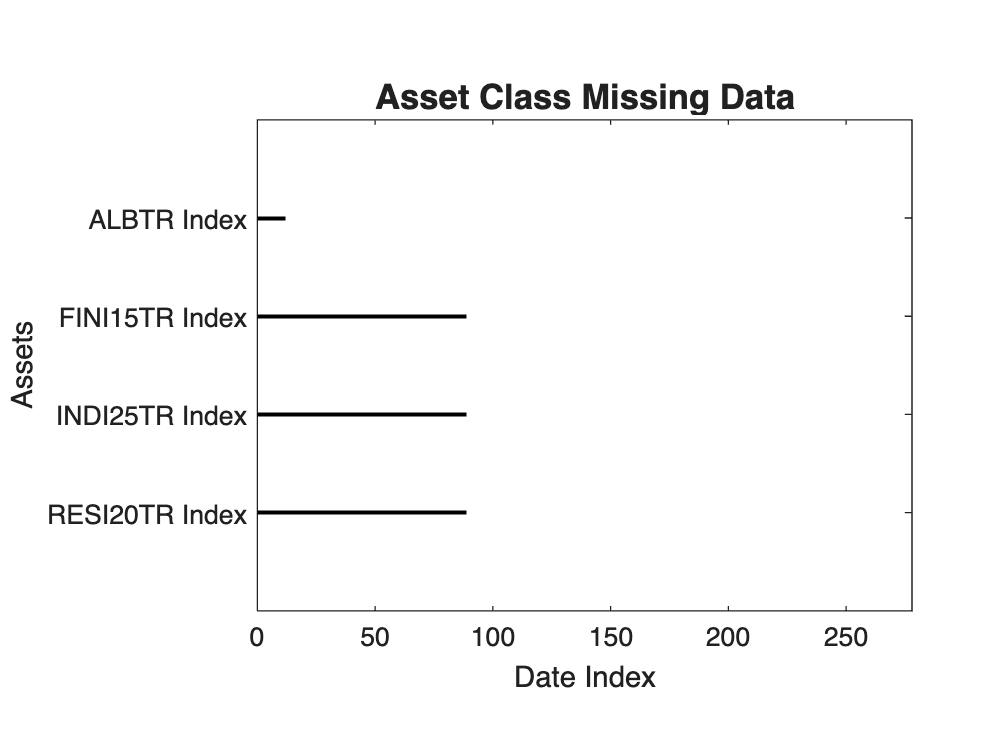

% missing data to plot in array
tickers = ASSETCL_dataTable.Properties.VariableNames;
na_array = transpose(isnan(table2array(ASSETCL_dataTable)));
ax = axes;

spy(na_array, 'black-',4);
set(gca,'ytick',1:4,'yticklabel',tickers);
pbaspect([8 6 1]);
ylabel("Assets");
xlabel("Date Index");
title("Asset Class Missing Data", 'FontSize', 13);

assetcl_NAplot = gca;
% close all

**Export NA Data plot**

exportName = 'ASSETCL_NAdata_plot.pdf';
exportgraphics(assetcl_NAplot,fullfile(imageExportpath,exportName),'Resolution',300)

**Remove NA:** 

We currently have 23 yrs of data, however, 15 yrs of historical data should suffice, therefore we can drop the dates prior to the initial existance of all indices:

[countNans,idx] = max(sum(isnan(ASSETCL_dataTable{:,:}),1));
rmmissingProxy =  ASSETCL_dataTable.Properties.VariableNames{idx};
ASSETCL_TableFilled = rmmissing(ASSETCL_dataTable,"DataVariables",rmmissingProxy);
spy(transpose(isnan(table2array(ASSETCL_TableFilled))))

**Extract the names of cols to change to valid field names (remove ' ',replace with '_')**

% rename the variables with underscores instead of spaces
newNames = strrep(ASSETCL_TableFilled.Properties.VariableNames, ' ', '_');
% remove the 'TR' the variables with underscores instead of spaces
newNames = strrep(newNames, 'TR', '');
ASSETCL_TableFilled = renamevars(ASSETCL_TableFilled, ASSETCL_TableFilled.Properties.VariableNames, newNames);

ASSETCL_TableFilled.Properties.Description = 'Raw asset class PX_LAST data: Market sector specific. Frequency; MONTHLY. Latest Update Aug23. Original Source: Bloomberg. Intended file naming: DATA-PROCESSED-ASSETCL-PX_LAST-M-TTABLE-20070630-20230228.mat';
ASSETCL_TableFilled.Properties.VariableDescriptions = {'FTSE JSE All Bond Index', 'JSE listed Financials Index',...
    'JSE listed Industrials Index','JSE listed Resources Index'};

ASSETCL_TableFilled.Properties

**SAVE Processed ASSETCL Datasets:**

exportName = 'DATA-PROCESSED-ASSETCL-PX_LAST-M-TTABLE-20070630-20230228.mat';
save(fullfile(dataExportpath,exportName),'ASSETCL_TableFilled');

## 3. Data Transformation

### 3.1 Compute Returns  

RESI_ret = 100*price2ret(ASSETCL_dataTable.("RESI20TR Index"))
scatter(ASSETCL_dataTable.Time(1:end-1),RESI_ret);
ytickformat('percentage');
title('RESI20 Index Returns');
ylabel('Returns');

### 4.2 ASSET CLASS Data Exploration

### 4.2.1 Plot Market Segment TRIs

% Visualise the data on a single plot
%plot the timeseries
% Create multiple line objects using matrix input to plot
plot1 = plot(ASSETCL_dataTable.Time,ASSETCL_dataTable{:,2:4},'LineWidth',1.5);
set(plot1(1),'DisplayName','FINI15TR Index');
set(plot1(2),'DisplayName','INDI25TR Index');
set(plot1(3),'DisplayName','RESI20TR Index');
ylabel("TRIs")
% Create title
title('TRI for SA Market Segments','FontSize',16);
%include the legend
% Create legend
legend1 = legend(ASSETCL_dataTable.Properties.VariableNames{:,2:3},'show');
set(legend1,'Location','northwest','FontSize',12);

MARKETSEG_TRI_plot = gca;

Export Market Segment Returns plot

exportName = 'MARKETSEG_TRI_plot.pdf'
exportgraphics(MARKETSEG_TRI_plot,fullfile(imageExportpath,exportName),'Resolution',300)

## Addional Build-On's 

- Code in checks eg:

- if files exist

- checking sequencial nature of dates (eg code way of confirming no missing date or if the spacing isn't desired frequency like monthly

         2.    Increase function flexibility:

-  see if we can make the functions more sufficiticated to be cope to a wider range of inputs (eg importfield2keep is very specific in what it generates as a lot is hard coded).

          3. Change file names to save using info from varaibles eg:

-  saving .mat files using function that pulls START and END date from the data and not entered manually.

#### Reference

- Lopez de Prado, Marcos. "Building diversified portfolios that outperform out-of-sample", Journal of Portfolio Management, 2016 

- [https://www.mathworks.com/help/stats/hierarchical-clustering.html](https://www.mathworks.com/help/stats/hierarchical-clustering.html)

- [https://www.mathworks.com/help/finance/asset-allocation-and-portfolio-optimization.html](https://www.mathworks.com/help/finance/asset-allocation-and-portfolio-optimization.html)